tou=[0.225,0.36,0.5,0.58,0.66,0.74,0.8]

tou =     0.2250    0.3600    0.5000    0.5800    0.6600    0.7400    0.8000


se_sc=0.1:0.1:0.7

se_sc =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000


sc=0.2

sc = 0.2000


eta=1

eta = 1

Cl_alpha_canard=0.11

Cl_alpha_canard = 0.1100

x_cg=1.5109

x_cg = 1.5109

x_ac=0.03

x_ac = 0.0300

se=tou*sc

se =     0.0450    0.0720    0.1000    0.1160    0.1320    0.1480    0.1600


AR_elevator=3:1:7

AR_elevator =      3     4     5     6     7


n=length(se)

n = 7

m=length(AR_elevator)                   %1 column is for 1 AR

m = 5

b=zeros(n,m);c=zeros(n,m);
for i=1:n
    for j=1:m
        b(i,j)=sqrt(AR_elevator(j)*se(i));
        c(i,j)=se(i)/b(i,j);
    end
end
b

b =     0.3674    0.4243    0.4743    0.5196    0.5612
    0.4648    0.5367    0.6000    0.6573    0.7099
    0.5477    0.6325    0.7071    0.7746    0.8367
    0.5899    0.6812    0.7616    0.8343    0.9011
    0.6293    0.7266    0.8124    0.8899    0.9612
    0.6663    0.7694    0.8602    0.9423    1.0178
    0.6928    0.8000    0.8944    0.9798    1.0583


c

c =     0.1225    0.1061    0.0949    0.0866    0.0802
    0.1549    0.1342    0.1200    0.1095    0.1014
    0.1826    0.1581    0.1414    0.1291    0.1195
    0.1966    0.1703    0.1523    0.1390    0.1287
    0.2098    0.1817    0.1625    0.1483    0.1373
    0.2221    0.1924    0.1720    0.1571    0.1454
    0.2309    0.2000    0.1789    0.1633    0.1512


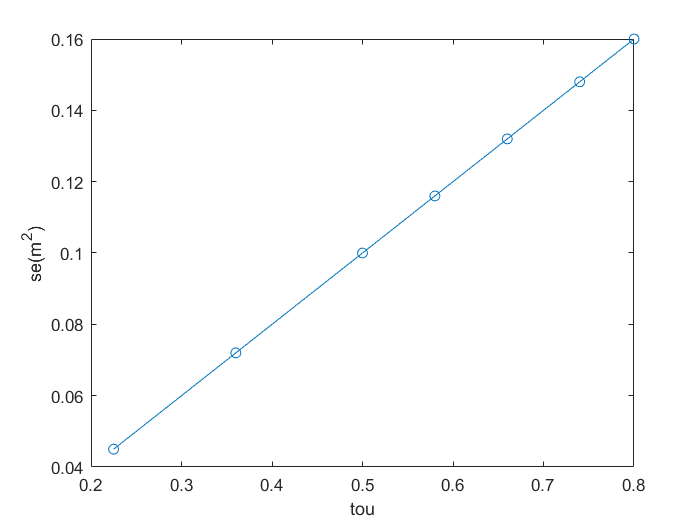

plot(tou,se,"Marker","o")
xlabel("tou")
ylabel("se(m^2)")

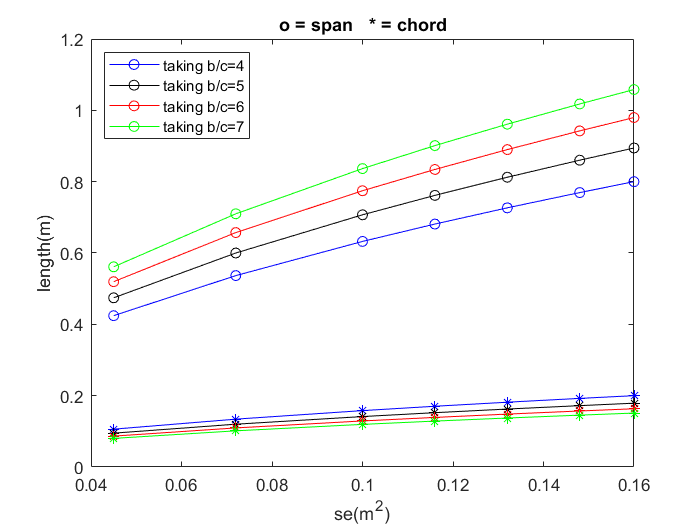

plot(se,b(:,2),"Marker","o","Color","b")
hold on
plot(se,b(:,3),"Marker","o","Color","k")
plot(se,b(:,4),"Marker","o","Color","r")
plot(se,b(:,5),"Marker","o","Color","g")
plot(se,c(:,2),"Marker","*","Color","b")
plot(se,c(:,3),"Marker","*","Color","k")
plot(se,c(:,4),"Marker","*","Color","r")
plot(se,c(:,5),"Marker","*","Color","g")
hold off
title("o = span   * = chord")
legend("taking b/c=4","taking b/c=5","taking b/c=6","taking b/c=7","Location","northwest")
xlabel("se(m^2)")
ylabel("length(m)")

Cl_dele=eta*(se(1)/sc)*Cl_alpha_canard*tou(1)

Cl_dele = 0.0056

Cm_dele=eta*(se(1)/sc)*Cl_alpha_canard*tou(1)*(x_cg-x_ac)

Cm_dele = 0.0082